clear all
load TR4_data.mat
syms t
syms q1(t) q2(t) q3(t)
syms Q1 Q2 Q3 Q1p Q2p Q3p
Q(1)=q1;
Q(2)=q2;
Q(3)=q3;
L=sym("l",[1 4]);
J=TR4_jacobian(Q,L);
Jp=diff(J,t)

$$Jp = \left(\begin{array}{ccc} -l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) & l_{4}\,\sin\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)-\frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2}-l_{4}\,\cos\left(q_{2}\left(t\right)\right)\,\cos\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & l_{4}\,\sin\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-l_{4}\,\cos\left(q_{2}\left(t\right)\right)\,\cos\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)\\ 0 & -l_{4}\,\cos\left(q_{3}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-l_{4}\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)-\frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2} & -l_{4}\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-l_{4}\,\cos\left(q_{3}\left(t\right)\right)\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) & 0 & l_{4}\,\sin\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right) \end{array}\right)$$

Jp=subs(Jp,diff(q2),Q2p);
Jp=subs(Jp,diff(q1),Q1p);
Jp=subs(Jp,diff(q3),Q3p);
Jp=subs(Jp,q1,Q1);
Jp=subs(Jp,q2,Q2);
Jp=subs(Jp,q3,Q3)

$$Jp = \left(\begin{array}{ccc} -\mathrm{Q1p}\,l_{1}\,\cos\left(Q_{1}\right) & \mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)-\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)-\frac{\sqrt{2}\,\mathrm{Q2p}\,l_{3}\,\cos\left(Q_{2}\right)}{2} & \mathrm{Q2p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)-\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)\\ 0 & -\frac{\sqrt{2}\,\mathrm{Q2p}\,l_{3}\,\sin\left(Q_{2}\right)}{2}-\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)-\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right) & -\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)-\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)\\ \mathrm{Q1p}\,l_{1}\,\sin\left(Q_{1}\right) & 0 & \mathrm{Q3p}\,l_{4}\,\sin\left(Q_{3}\right) \end{array}\right)$$

Jp=matlabFunction(Jp)

Jp = function_handle with value:
    @(Q1,Q2,Q3,Q1p,Q2p,Q3p,l1,l3,l4)reshape([-Q1p.*l1.*cos(Q1),0.0,Q1p.*l1.*sin(Q1),sqrt(2.0).*Q2p.*l3.*cos(Q2).*(-1.0./2.0)-Q2p.*l4.*cos(Q2).*cos(Q3)+Q3p.*l4.*sin(Q2).*sin(Q3),sqrt(2.0).*Q2p.*l3.*sin(Q2).*(-1.0./2.0)-Q2p.*l4.*cos(Q3).*sin(Q2)-Q3p.*l4.*cos(Q2).*sin(Q3),0.0,-Q3p.*l4.*cos(Q2).*cos(Q3)+Q2p.*l4.*sin(Q2).*sin(Q3),-Q2p.*l4.*cos(Q2).*sin(Q3)-Q3p.*l4.*cos(Q3).*sin(Q2),Q3p.*l4.*sin(Q3)],[3,3])


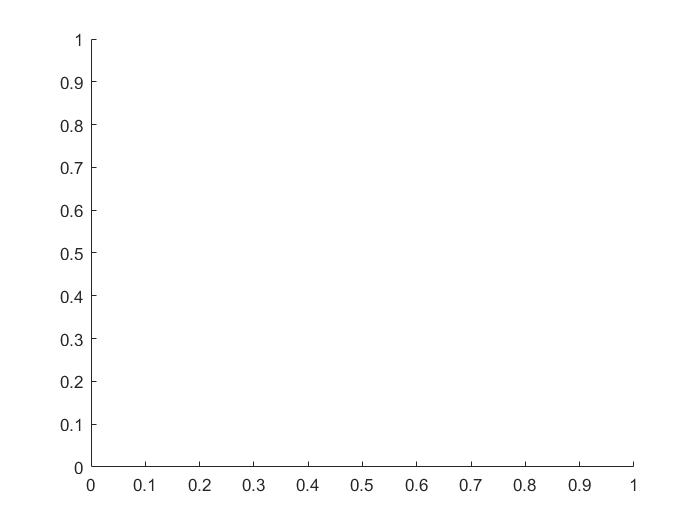

Error using fimplicit3>singleFimplicit (line 172)
Function input may have up to three variables.

Error in fimplicit3>@(f)singleFimplicit(cax,f,limits,extraOpts,args) (line 146)
    hObj = cellfun(@(f) singleFimplicit(cax,f,limits,extraOpts,args),fn,'UniformOutput',false);

Error in <a href="ma

detJ=det(J);

assume(Q,'positive')
simplify(detJ)
detJ=matlabFunction(detJ);
J=matlabFunction(J)

## calcolo Jacobiano

clear all
Q=sym("q",[1 3])

$$Q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

L=sym("l",[1 4])

$$L = \left(\begin{array}{cccc} l_{1} & l_{2} & l_{3} & l_{4} \end{array}\right)$$

load TR4_data.mat
[M01_ M1_1 M12 M23]=TR4_positionMat(Q,L);
M01=M01_*M1_1;
M02=M01*M12;
M03=M02*M23;
S=M03*[0 0 0 1]'

$$S = \left(\begin{array}{c} \frac{\sqrt{2}\,l_{2}}{2}+l_{1}\,\cos\left(q_{1}\right)+l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+\frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \frac{\sqrt{2}\,l_{2}}{2}+\frac{\sqrt{2}\,l_{3}}{2}-l_{1}\,\sin\left(q_{1}\right)-l_{4}\,\sin\left(q_{3}\right)\\ 1 \end{array}\right)$$

S=S(1:3)

$$S = \left(\begin{array}{c} \frac{\sqrt{2}\,l_{2}}{2}+l_{1}\,\cos\left(q_{1}\right)+l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+\frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \frac{\sqrt{2}\,l_{2}}{2}+\frac{\sqrt{2}\,l_{3}}{2}-l_{1}\,\sin\left(q_{1}\right)-l_{4}\,\sin\left(q_{3}\right) \end{array}\right)$$

J=jacobian(S,Q)

$$J = \left(\begin{array}{ccc} -l_{1}\,\sin\left(q_{1}\right) & -\frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}-l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & -l_{4}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ 0 & l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+\frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2} & -l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ -l_{1}\,\cos\left(q_{1}\right) & 0 & -l_{4}\,\cos\left(q_{3}\right) \end{array}\right)$$

Error using fimplicit3>singleFimplicit (line 172)
Function input may have up to three variables.

Error in fimplicit3>@(f)singleFimplicit(cax,f,limits,extraOpts,args) (line 146)
    hObj = cellfun(@(f) singleFimplicit(cax,f,limits,extraOpts,args),fn,'UniformOutput',false);

Error in <a href="ma

detJ=det(J);
fimplicit3(detJ)

J=matlabFunction(J)

## calcolo singolarità

load TR4_data.mat
Sol=[];
point=[];
Q=[];
for q1 =0:pi/4:2*pi
    for q2 = 0:pi/4:2*pi
        for q3 = 0:pi/4:2*pi
            q=[q1,q2,q3];
            sol=abs(detJ(q1,q2,q3));
            Sol=[Sol sol];
            Q=[Q q'];
        end
    end
end
save Punti_singolarita point Sol Q

## Ricerca singolarità

load Punti_singolarita.mat
load Absolute_Solution
close all
sing=[];
Q_=[];
media=mean(Sol);
for i=1:length(Sol)
    el=Sol(i);
    if el<0.1
        sing=[sing el];
        Q_=[Q_ Q(:,i)];
     end
end


## print data

close all
plot(Sol,'.')
plot(sing,'.')
P=[];
for i=1:length(sing)
    figure(1)
    point=TR4_dirKin(Q_(:,i)',link);
    plot3(point(1),point(2),point(3),'o')
    P=[P point];
    hold on
    %TR4_plot(Q_(:,i)',link,'b',1)
    
end
X0=[];
Y0=[];
Z0=[];
Qy=[];
for i=1:length(P(1,:))
    if(P(1,i)==0)
        X0=[X0 P(:,i)];
    end
    if(P(2,i)==0)
        Y0=[Y0 P(:,i)];
        Qy=[Qy Q_(:,i)];
    end
    if(P(3,i)==0)
        Z0=[Z0 P(:,i)];
    end
end
for i=1:length(Y0(1,:))
    figure(2)
    plot3(Y0(1,i),Y0(2,i),Y0(3,i),'o')
    hold on
    TR4_plot(Qy(:,i)',link,'b',2)
    close all
end
figure
plot(Q_(1,:))
plot(Q_(2,:))
plot(Q_(3,:))

## prova genetic algorithm

close all
opt=optimoptions('ga',"FunctionTolerance",10^-9,"ConstraintTolerance",10^-6)
[x,fval,flag]=ga(@detJacobian,3,opt)
TR4_plot(x,link,'r',1)

close all
TR4_plot([0 0 0],link,'b',32)

## disegno determinante jacobiano

clear all
close all
load TR4_data.mat
Q=sym("q",[1 3]);
detJ=detJacobian(Q,link)

$$detJ = -\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}\,\cos\left(q_{3}\right)}{31250}-\frac{625059750189947\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}}{36893488147419103232}+\frac{\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}}{31250}+\frac{625059750189947\,\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{36893488147419103232}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{31250}-\frac{625059750189947\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{36893488147419103232}$$

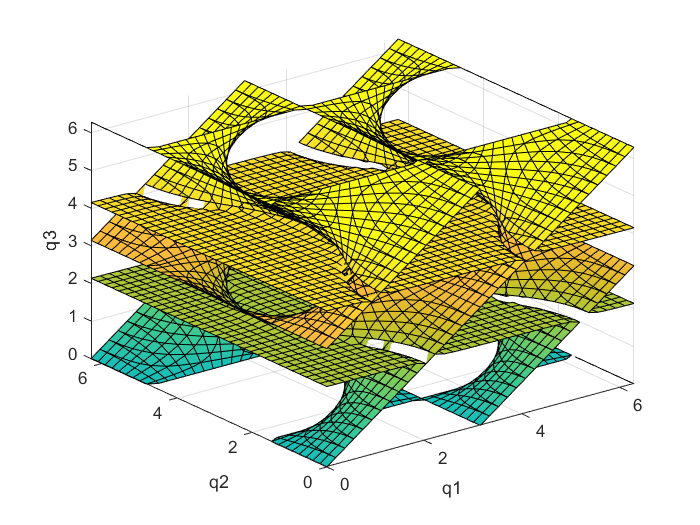

fimplicit3(detJ)
xlim([0 2*pi])
ylim([0 2*pi])
zlim([0 2*pi])
xlabel("q1")
ylabel("q2")
zlabel("q3")

eq1=detJ==0

$$eq1 = -\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}\,\cos\left(q_{3}\right)}{31250}-\frac{625059750189947\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}}{36893488147419103232}+\frac{\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}}{31250}+\frac{625059750189947\,\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{36893488147419103232}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{31250}-\frac{625059750189947\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{36893488147419103232}=0$$

%SOL=solve(eq1,Q)
F=matlabFunction(detJ)

F = function_handle with value:
    @(q1,q2,q3)cos(q1).*cos(q2).^2.*sin(q3).*(-1.694227847722968e-5)+(cos(q2).*cos(q3).^2.*sin(q1))./3.125e+4-cos(q1).*sin(q2).^2.*sin(q3).*1.694227847722968e-5+cos(q2).*cos(q3).*sin(q1).*1.694227847722968e-5-(cos(q1).*cos(q2).^2.*cos(q3).*sin(q3))./3.125e+4-(cos(q1).*cos(q3).*sin(q2).^2.*sin(q3))./3.125e+4


F=@(X)F(X(1),X(2),X(3))

F = function_handle with value:
    @(X)F(X(1),X(2),X(3))


fsolve(F,[0 0 0])


Equation solved at initial point.

fsolve completed because the vector of function values at the initial
point is near zero as measured by the value of the function tolerance,
and the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =      0     0     0


for q1 = linspace(0,2*pi,181)
    for q2 = linspace(0,2*pi,181)
        for  q3 = linspace(0,2*pi,181)
%             n = detJacobian([q1 q2 q3],link)
%             if n <10e-5 && n >-10e-5
%                 disp(q1)
%                 disp(q2)
%                 disp(q3)
%             end
            [Q,fval]=fsolve(F,[q1 q2 q3])
        end
    end
end


Equation solved at initial point.

fsolve completed because the vector of function values at the initial
point is near zero as measured by the value of the function tolerance,
and the problem appears regular as measured by the gradient.

<stopping criteria details>


Q =      0     0     0


fval = 0


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000    0.0000    0.0349


fval = -1.7074e-06


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000    0.0000    0.0698


fval = -3.4086e-06


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000         0    0.1047


fval = -5.0975e-06


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000         0    0.1396


fval = -6.7681e-06


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000         0    0.1745


fval = -8.4143e-06


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000    0.0000    0.2094


fval = -1.0030e-05


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000         0    0.2443


fval = -1.1610e-05


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


Q =     0.0000   -0.0000    0.2793


fval = -1.3149e-05